Este script usa la función RegionProps para identificar objetos en imágenes y muchas de sus características (ver ayuda de la función). Con esta información podemos procesar imágenes e identificar objetos y características de los mismos.

Se ha aplicado a una imagen de ejemplo muy simplificada. Las imágenes reales tomadas de una cámara se ven muy afectadas por condiciones de iluminación, factores de escala, etc., que hacen que este tipo de procesamiento pueda resultar muy complejo, especialmente el referido al suavizado, binarizado, eliminación de objetos pequeños y de huecos, etc.

La imagen se podría cargar de la siguiente manera (también se podría obtener directamente de la cámara como se indica)

Cargar imagen

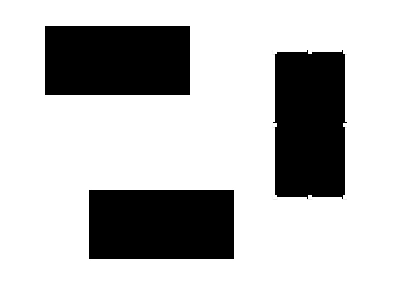

clear, close all, clc
img = imread('prueba.jpg'); % Reemplaza 'prueba.jpg' con el nombre de tu imagen
imshow(img)

Obtener imagen de la cámara

cam = webcam;
preview(cam);
img = snapshot(cam);
imshow(img);

img = imread('circlesBrightDark.png');

Independientemente del procedimiento de obtención, una vez cargada la imagen, puede ser recomendable suavizarla y en cualquier caso hay que binarizarla (convertirla a blanco y negro, previamente se ha convertido a imagen de una sola capa en escala de grises). El umbral se puede especificar manualmente o se puede intentar calcular automáticamente mediante métodos como el de Otsu.

img_gris = rgb2gray(img); % Convertir a escala de grises
imshow(img_gris);

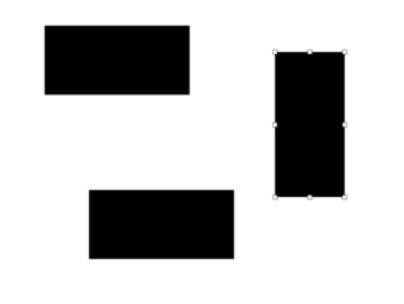


img_suavizada = imgaussfilt(img_gris, 2); % Aplicar suavizado gaussiano
imshow(img_suavizada);


umbral = graythresh(img_suavizada); % Umbral automático usando el método de Otsu
img_binaria = imbinarize(img_suavizada, umbral);

El resto del script considera que el fondo de la imagen es negro, y los objetos blancos. Si no es así (como es nuestro caso), se puede invertir la imagen con la siguiente instrucción

img_binaria = imcomplement(img_binaria)

img_binaria = 674×824 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

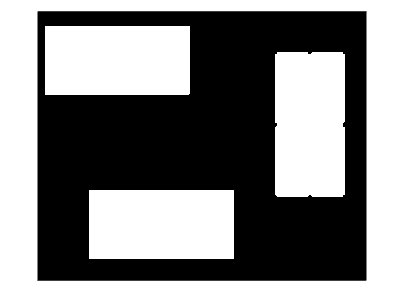

imshow(img_binaria);

Ahora con esas consideraciones procedemos a tratar la imagen: se eliminan regiones por debajo de una dimensión requerida, se eliminan agujeros, ... .

img_binaria_2 = bwareaopen(img_binaria, 10); % Eliminar regiones pequeñas
img_binaria_3 = imfill(img_binaria_2, 'holes'); % Rellenar agujeros
imshow(img_binaria_3);

Una vez lo tengamos todo listo, podemos proceder a identificar objetos

stats = regionprops("table",img_binaria_3,'all')

stats = 3×30 table
    Area        Centroid                 BoundingBox                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Podemos representar para verificar el resultado

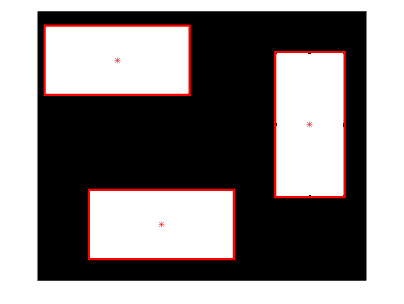

imshow(img_binaria_3)

hold on

plot(stats.Centroid(:,1), stats.Centroid(:,2), 'r*')%Representamos los centroides identificados
n_objects = height(stats);

for i = 1:n_objects %Representamos las cajas que encierran a cada objeto
    rectangle('Position', stats(i, :).BoundingBox, 'EdgeColor', 'r', 'LineWidth', 2);
end

hold off

Con la información proporcionada se podría intentar clasificar cada uno de los objetos. La función discriminante podría elaborarse mediante aprendizaje automático.